# EMG Pattern Recognition Example

This script demonstrates the complete workflow for developing an EMG-based pattern recognition system, including loading and preprocessing the data, extracting features, exploring various algorithms, and training and evaluating a classification model.

## EMG Data Collection

In this example, data for seven different classes of hand motion (3 DoF and a rest class) were collected from an able-bodied subject. These motions are 

- no movement

- hand close

- hand open

- wrist flexion  

- wrist extension 

- supination 

- pronation 

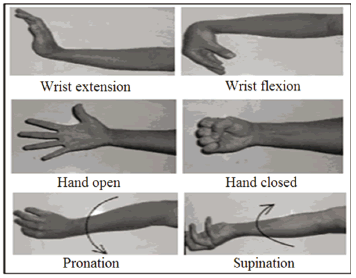

Six EMG signals were recorded from muscles on one side of the subject’s forearm. The monitored muscles included the *flexor carpi ulnaris* (FCU), *flexor carpi radialis*(FCR), *extensor carpi ulnaris* (ECU), *extensor carpi radialis*(ECR), *palmaris longus* (PL), and *extensor pollicis longus* (EPL). The EMG electrodes were placed over the anatomical locations described in [[1](https://www.amazon.com/Anatomical-Guide-Electromyographer-Limbs-Trunk/dp/0398086494)].

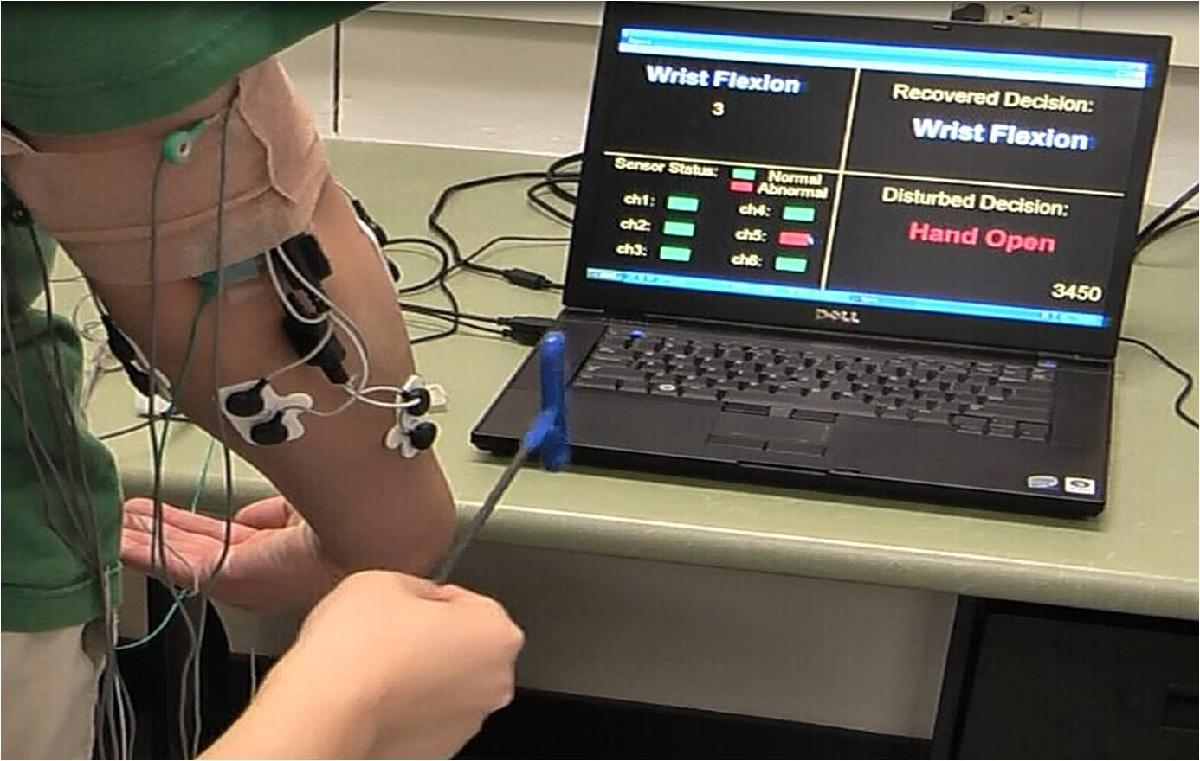

Electrode placement was prepared by shaving any excessive body hair in the site regions, and applying an alcohol prep pad. Disposable self-adhesive bipolar surface EMG electrodes (Norotrode, Myotronics Inc.) were used in this study. Each Norotrode was connected to an EMG pre-amplifier ([MA-420-002](https://www.motion-labs.com/prod_preamp_ma420.html), Motion Lab System Inc.), which band-pass filtered the EMG signals between 10 Hz and 3,500 Hz with a pass-band gain of 20. 

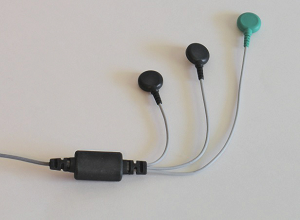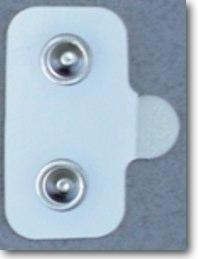

A single ground electrode was placed on the back of the elbow for all the subjects. All data were collected by a 16-channel EMG system ([MA-300-16](https://www.motion-labs.com/prod_emg_systems_xvi.html), Motion Lab System Inc), digitized by a data acquisition system with 16-channel 16-bit analog-to-digital converters, and sampled at 1000 Hz per channel.

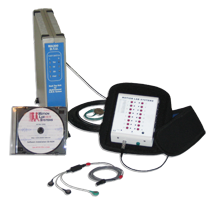

## Experimental Protocol

For each subject, **three trials of data** were collected. Each trial consisted of **two repetitions of the following seven types of motion classes**: no movement, wrist supination/pronation, hand close/open, and wrist flexion/extension. 

The subjects were not restrained in any way during data collection. All contractions were performed at a speed and strength determined by the subject, and they were encouraged to contract at a level that they felt comfortable to repeat for the duration of the experiment. Before the training trial started, the subjects were instructed to perform each motion task multiple times while the raw signals were viewed in real-time. The experimenter ensured that the signal quality of each EMG channel was good and that the gains of the amplifiers were appropriately set to avoid signal saturation. A Matlab implemented software GUI was developed to instruct the subject to elicit and relax contractions. During the data collection, upon seeing a command of a motion class, the subject began the instructed contraction, and held the final position until seeing a command instructing them to relax the contraction. 

**The duration of each motion was 4 s, and the rest periods were 5 s between successive contractions. There was a 3 s countdown display to cue the subject before switching to the next motion.**

## Dataset Preparation

The dataset is located in the */EMG_PR_code/data* folder. For each motion class, there are six txt files stored in the folder. Each file contains 2000 x 6 data, which is the central 2 s data from each performed motion.

In this example, we created two sub-folders */EMG_PR_code/data/train* and */EMG_PR_code/data/test* to partition the dataset into training and testing sets. Specifically, files with names "ClassName1", "ClassName3", and "ClassName5" are stored in the train folder, while files with names "ClassName2", "ClassName4", and "ClassName6" are stored in the test folder.

#### Raw Data at a glance

Current plot held


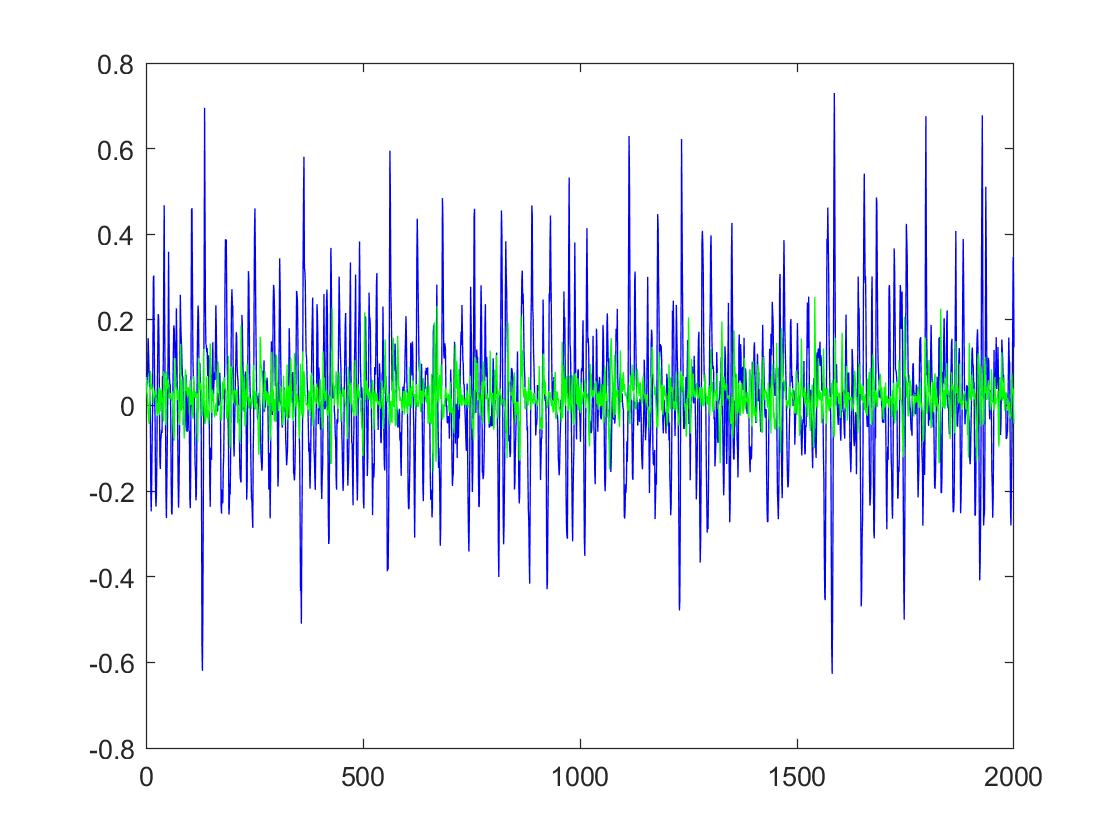

Current plot held


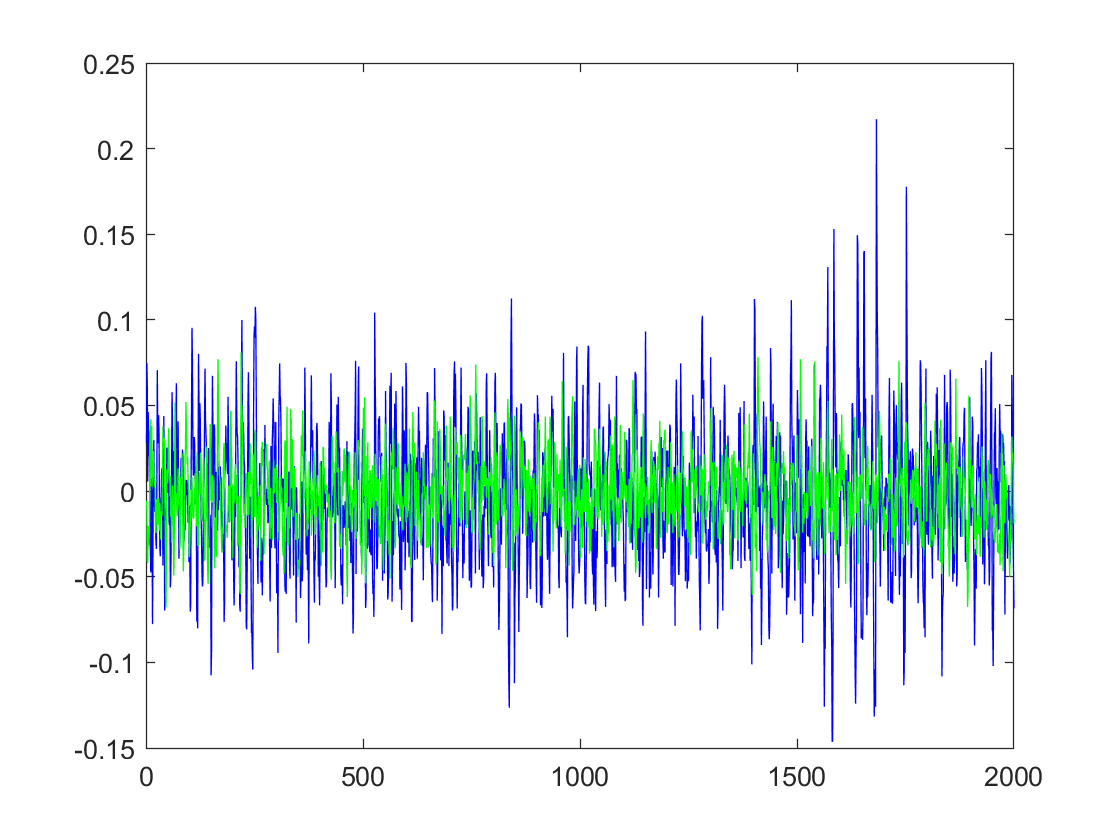

Current plot held


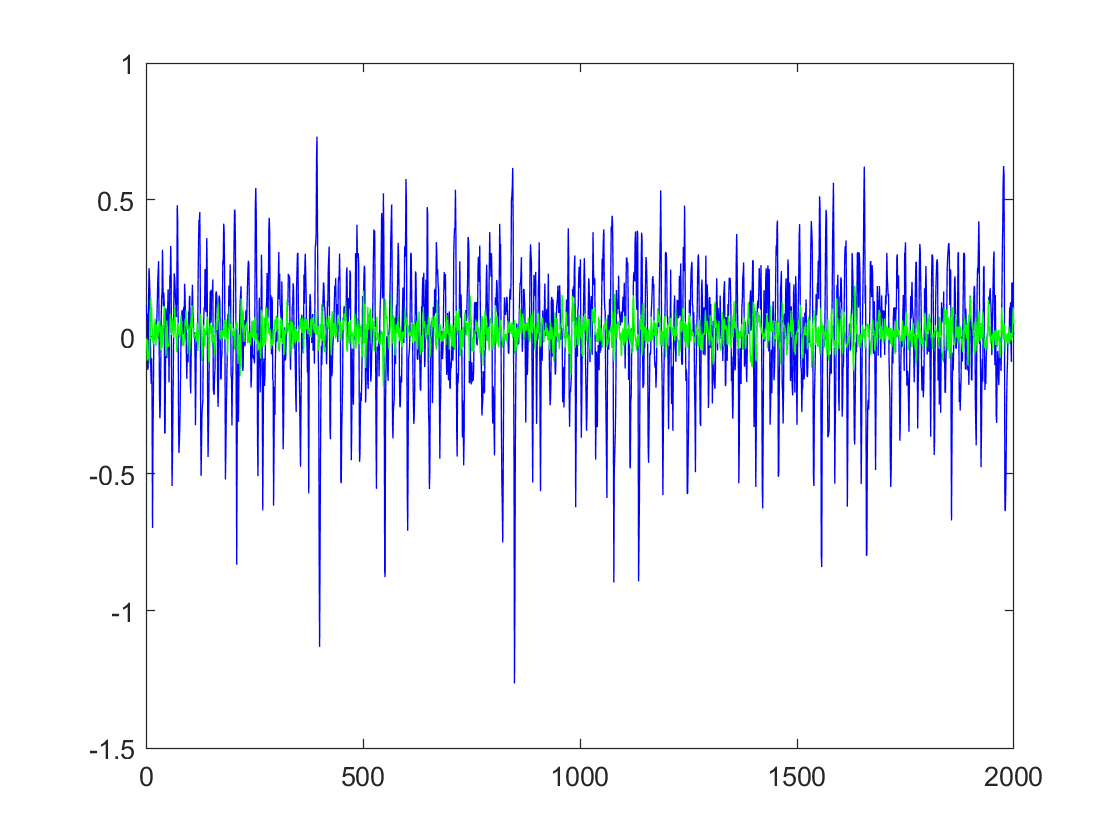

Current plot held


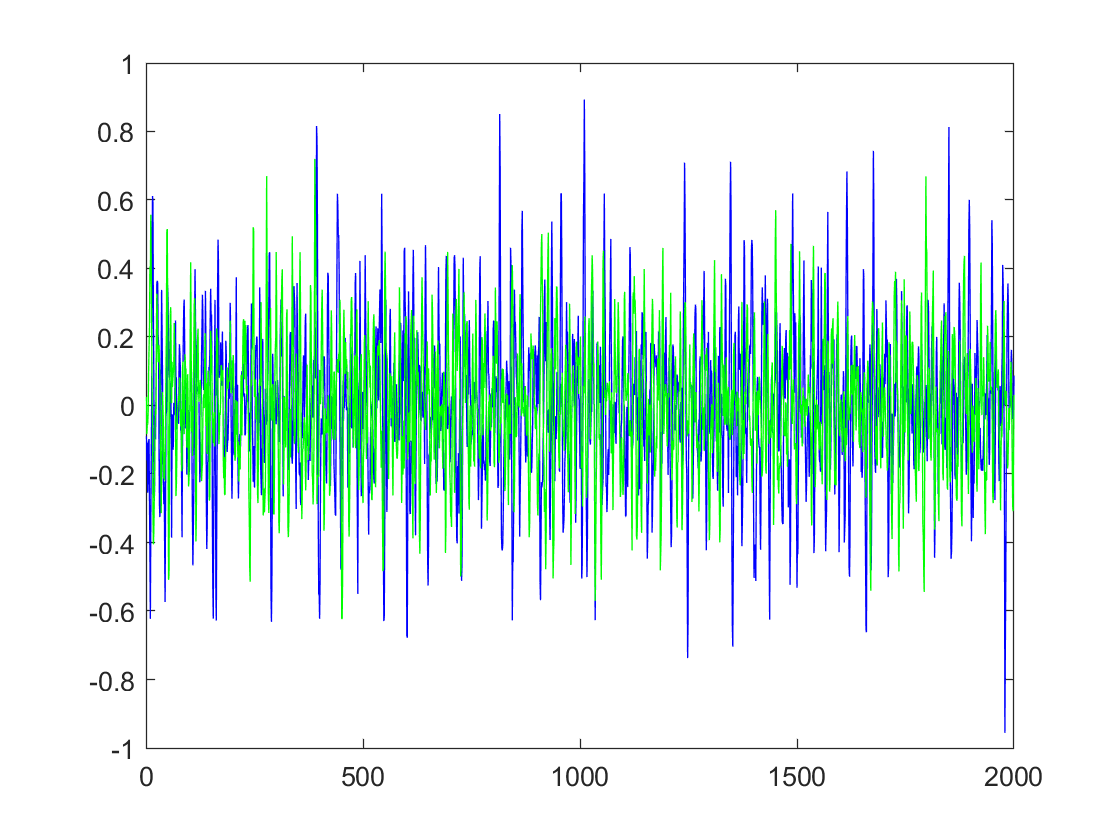

Current plot held


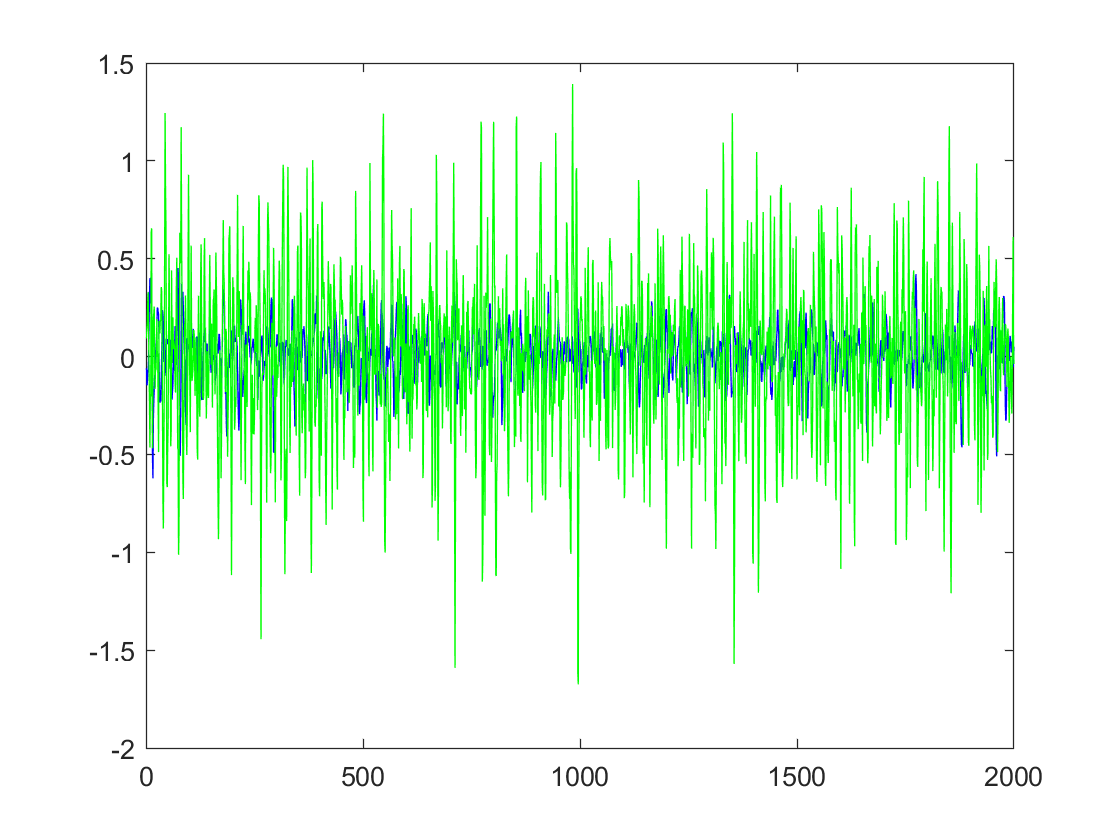

Current plot held


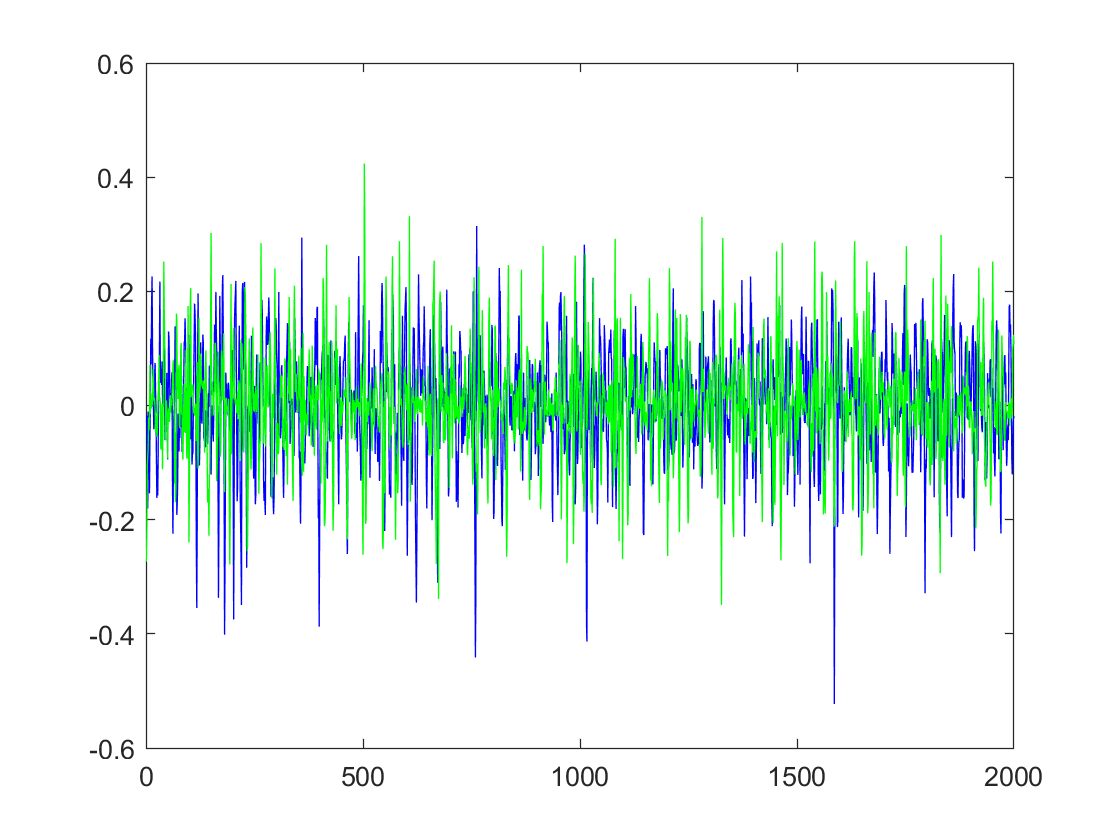

clear all
close all
load ../data/HandClose1.txt
load ../data/HandOpen1.txt

for i=1:6
    figure
    plot(HandClose1(:,i),'b')
    hold
    plot(HandOpen1(:,i),'g')
end

#### Feature at a glance

WL=160;         %window length
WInc=20;        %window increment

Feature_matrix_HC = []; % Feature matrix for the Hand Close class
Index=1:WL;
RawEMG_HC = HandClose1;
while Index(end)<=size(RawEMG_HC,1)
      Feature_vector = MAV(RawEMG_HC(Index,:),WL,WInc); % feature vector for one window
      Feature_matrix_HC=[Feature_matrix_HC,Feature_vector];    % feature matrix 
      Index=Index+WInc;
end

Error using EMG_PR_LiveScript>MAV
Too many input arguments.


Feature_matrix_HO = []; % Feature matrix for the Hand Open class
Index=1:WL;
RawEMG_HO = HandOpen1;
while Index(end)<=size(RawEMG_HO,1)
      Feature_vector = MAV(RawEMG_HO(Index,:),WL,WInc); % feature vector for one window
      Feature_matrix_HO=[Feature_matrix_HO,Feature_vector];    % feature matrix 
      Index=Index+WInc;
end

Plot the MAV feature

for i=1:6
    figure
    plot(Feature_matrix_HC(i,:), 'b');
    hold
    plot(Feature_matrix_HO(i,:), 'g');
end


## Feature Extraction

Run the *FeatureMatrixGen.m* script to extract features from the raw data to form a feature matrix to train a classifier model. In this script, we define the window length and windorw increment to be 160 and 20 data points, respectively. 

For each analysis window, four features 

- mean absolute value (mav)

- number of zero crossings (ZC)

- waveform length (len)

- number of slope sign changes (turn) [[2](https://ieeexplore.ieee.org/document/204774)]

are extracted from each EMG signal by the *tdfeats.m* script and then the features from all six EMG channels are concatenated into a **24x1 feature vector**. 

The feature vectors from all analysis windows of all classes are then formed as a feature matrix ***TrainFeature*** for training purpose. The class labels of all the windows are stored in a vector ***TrainClass***.

FeatureMatrixGen
clear all
load FeatureMatrixGen.mat

Let's take a look at the generated feature matrix by plotting the data. 

figure
plot(TrainFeature(1,:));
hold

Current plot held


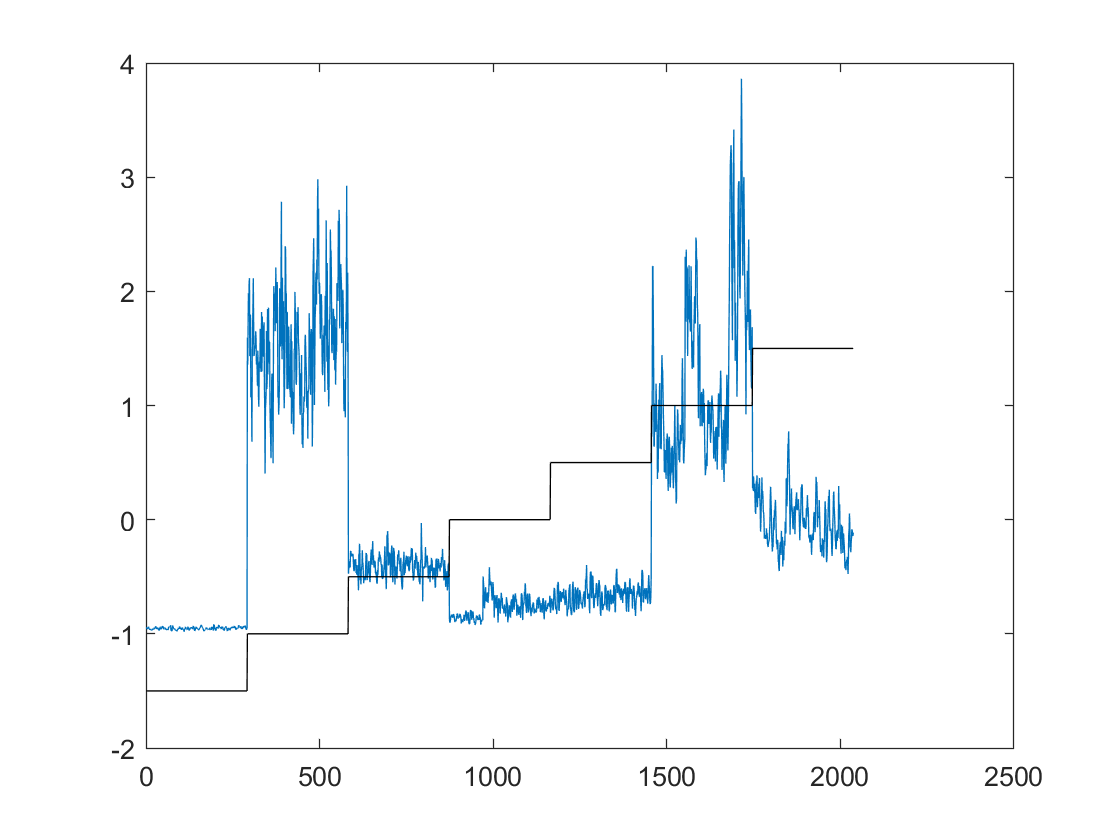

plot(TrainClass/2-2,'k');

## Classification - Train a Model

Now we can train a classifier model using the feature matrix generated in the previous step. We could either write our own script of classification algorithms or use the MATLAB built-in ***Classification Learner*** app. 

Let's first try the ***Classification Learner*** app.

classificationLearner

The Classification Learner requires an input combining the feature variables and the class labels, so we define a variable ***TrainTable*** to combine ***TrainFeature*** and ***TrainClass***.

TrainTable = [TrainFeature; TrainClass];

We can then select ***TrainTable*** as the input of the ***ClassificationLearner*** workspace. Select "Use rows as variables" because the features and the class label are stored in rows in ***TrainTable ***(25 by 1953). 

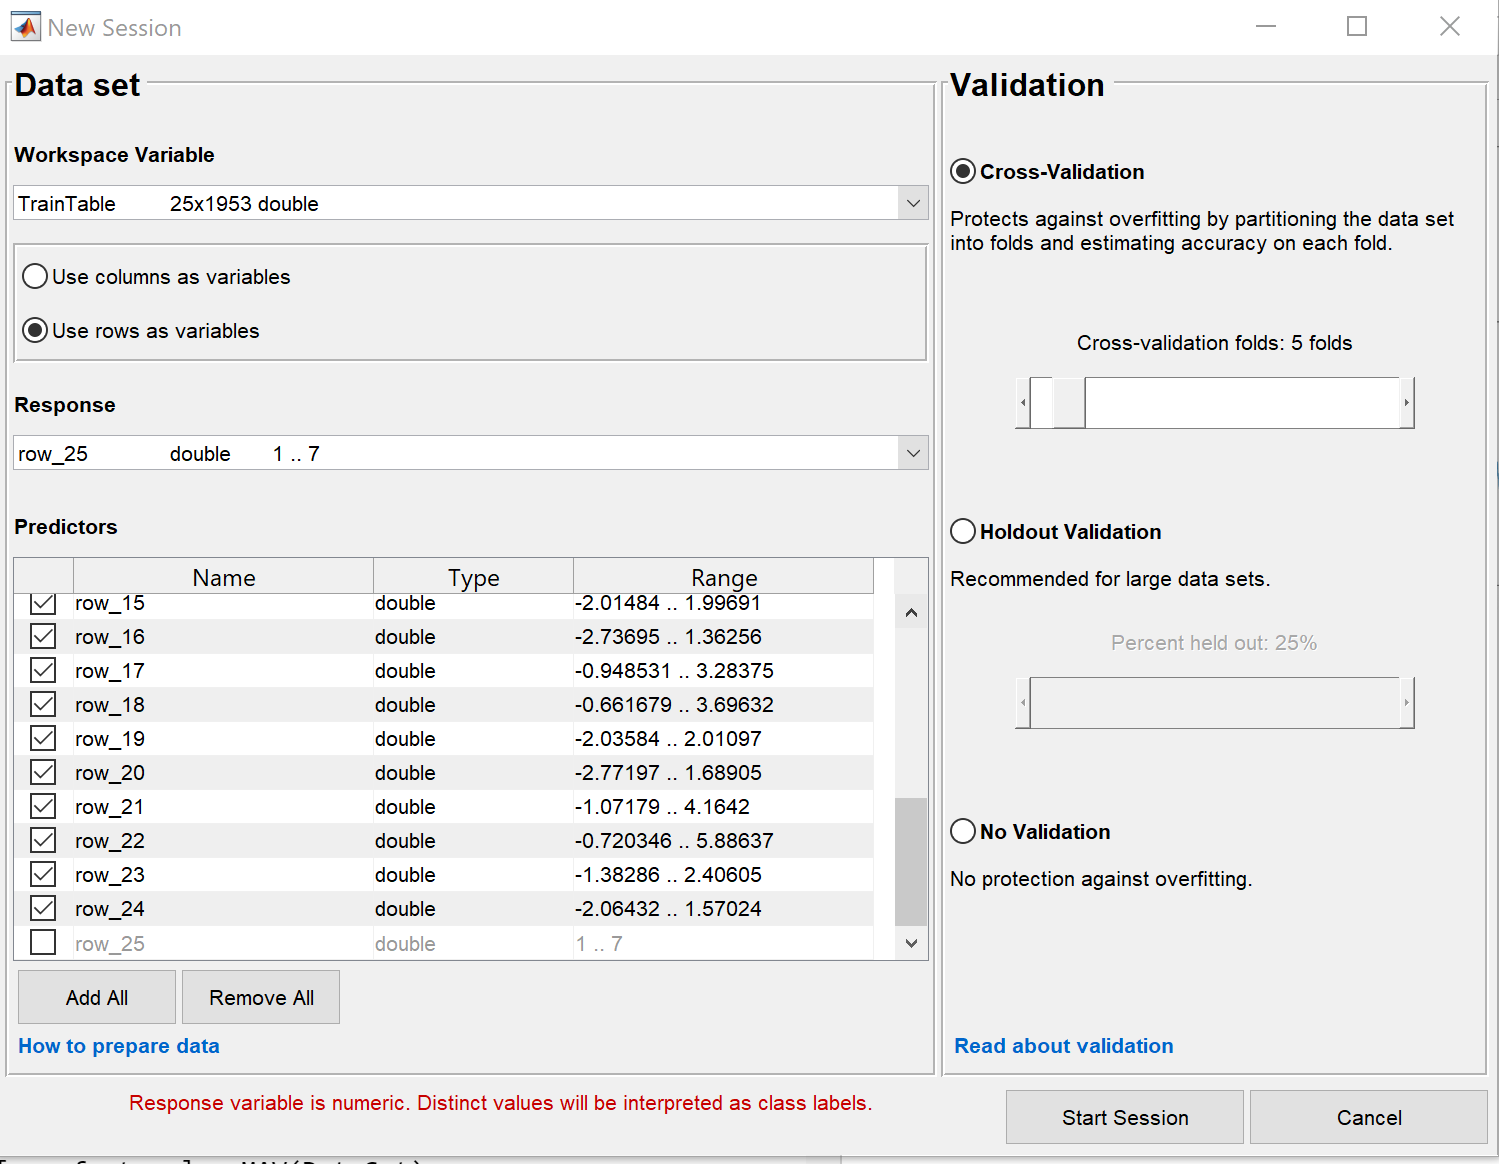

We choose the 5-fold cross validation method to validate the trained model, which means the training dataset is divided into 5 groups. 

The general procedure of a k-fold cross validation is as follows:

- Shuffle the dataset randomly.

- Split the dataset into k groups

- For each unique group:

- Take the group as a hold out or test data set

- Take the remaining groups as a training data set

- Fit a model on the training set and evaluate it on the test set

- Retain the evaluation score and discard the model

        4. Summarize the skill of the model using the sample of model evaluation scores

After the session starts, we can select the features we want to include in the training, the training algorithm, whether we want to do a feature reduction process, and some other configuration options before the training starts. Once all the configuration is done, we can press the train button to start building the model. For example, if we select only the MAV feature from each EMG channel, and use the linear discriminant algorithm, the trained model provides a 99.9% validation accuracy as shown below. 

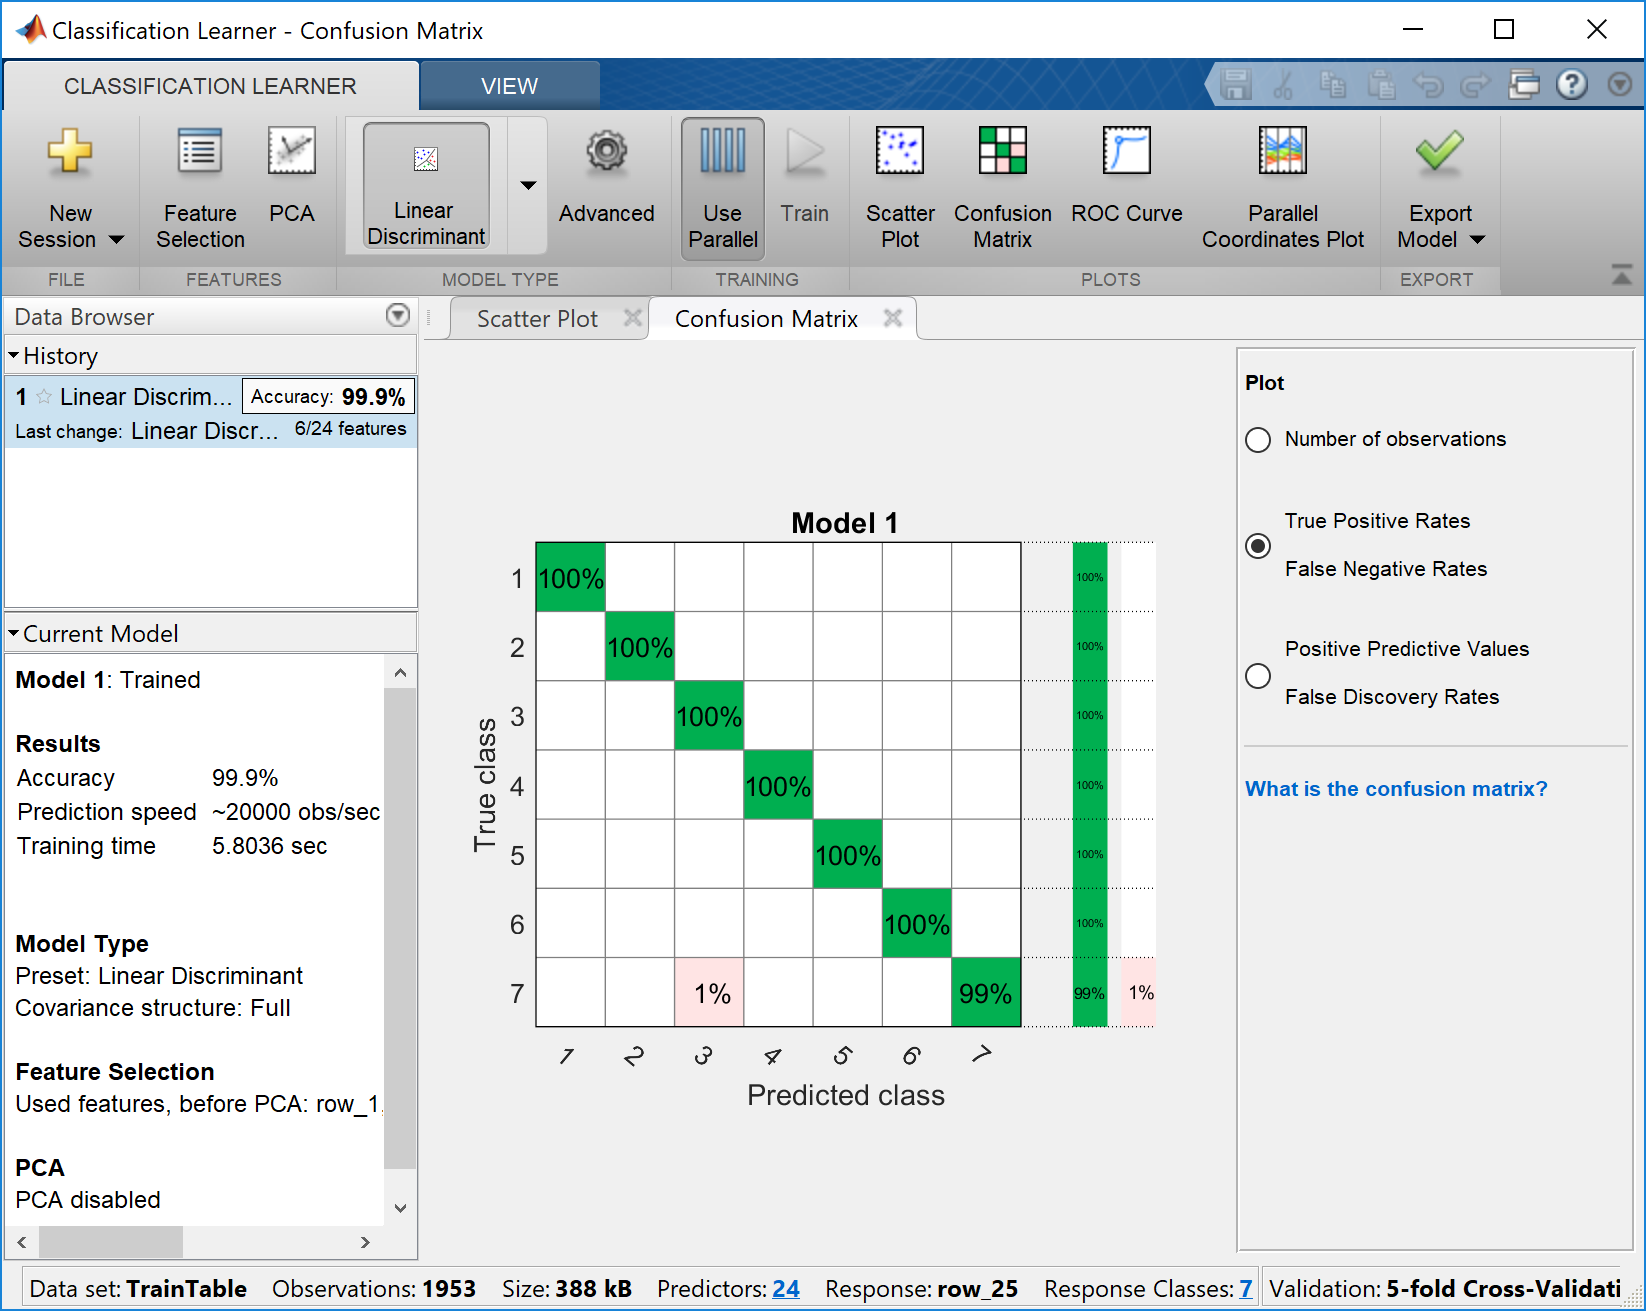

We can export the model to our workspace and then test it on new data, in this case, the data in the */EMG_PR_code/data/test *folder. In this example, we name the exported model as ***LDA_6feat***.

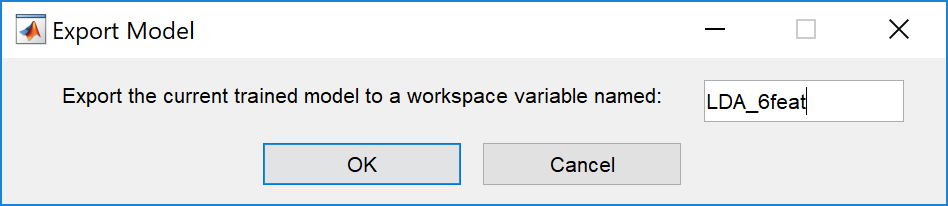

## Classification - Test the Model on New Data

To make predictions using the exported model LDA_6feat. We write the code below using the feature matrix generated from the test dataset (***TestFeature***) as the input. Please note that TestFeature only contains features, the class label is not included. And then, we compare the prediction results with the ground truth, i.e., the true labels of the analysis windows in the test set by calling the ***LDA_test_accuracy*** function. 

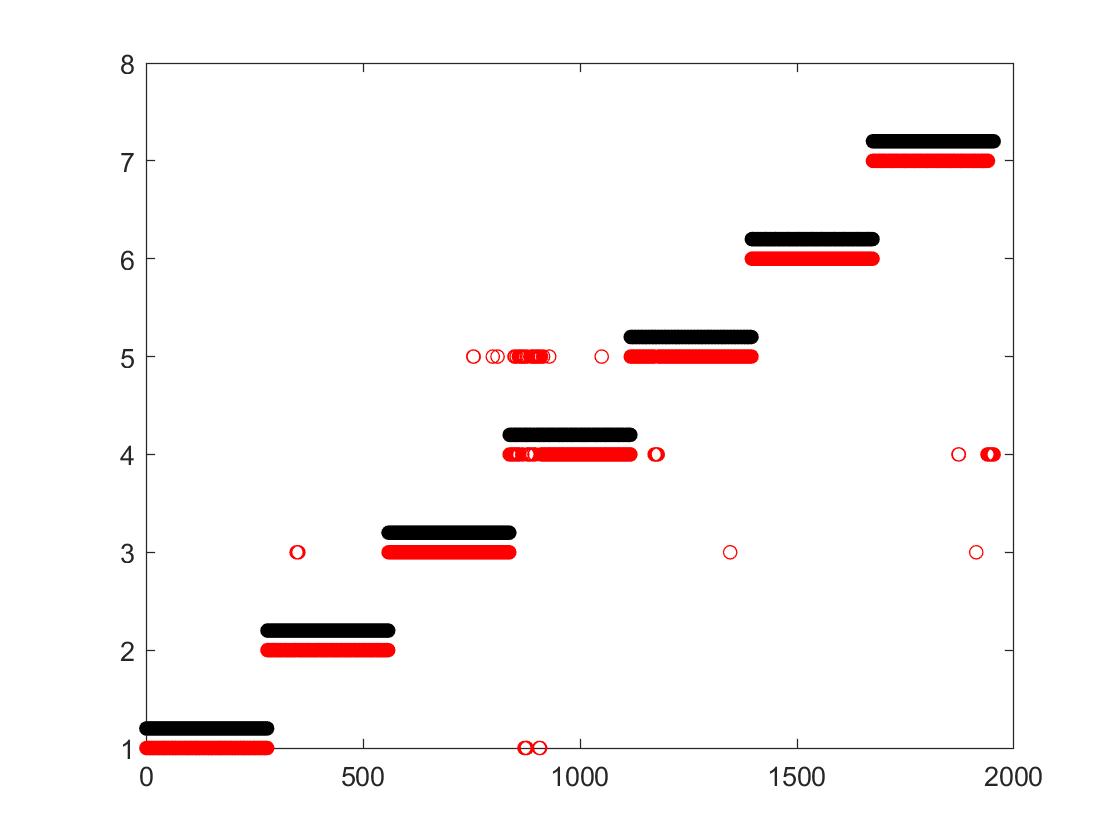

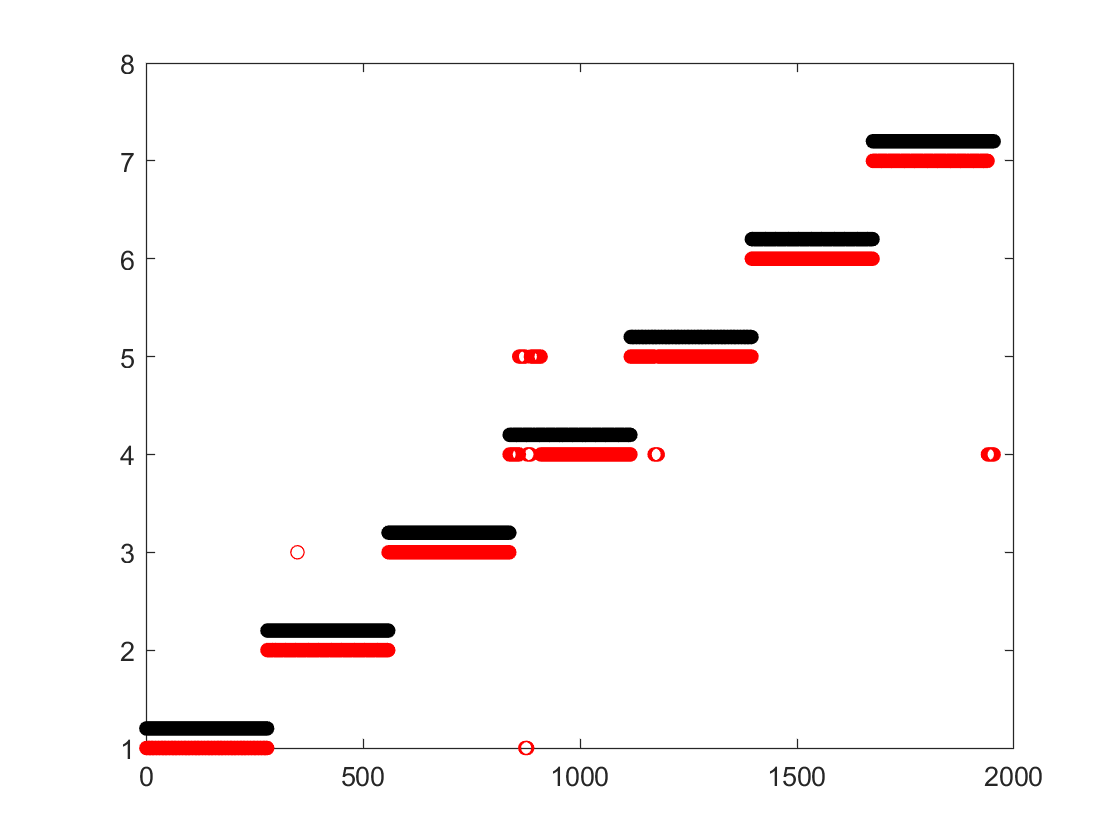

accuracy = 0.9601

accuracy_MV = 0.9667

save LDA_2feat.mat LDA_2feat  
TestResult = LDA_2feat.predictFcn(TestFeature); 
[accuracy, accuracy_MV]=LDA_test_accuracy(TestResult,TestClass, 2)

The testing accuracy is 99.44%.

## Helper Functions

Define a function to calculate the MAV feature

function [mav_feature] = MAV(DataSet)
    Ntotal = size(DataSet,1);   %number of data points in each channel
    Nsig = size(DataSet,2);     %number of channels
    DataSet = DataSet - ones(Ntotal,1)*mean(DataSet);   %calculate mean of each channel, and subtract it from the raw EMG, so now the new mean of each channel should be zero
    for SigNum = 1:Nsig
        mav_feature(SigNum,1) = mean(abs(DataSet(:,SigNum)));
    end
end